clc;
close all;
clear all;
addpath('ga');
initializeUnicycleModel;
initializeQuadrotorModel;

## Consensus

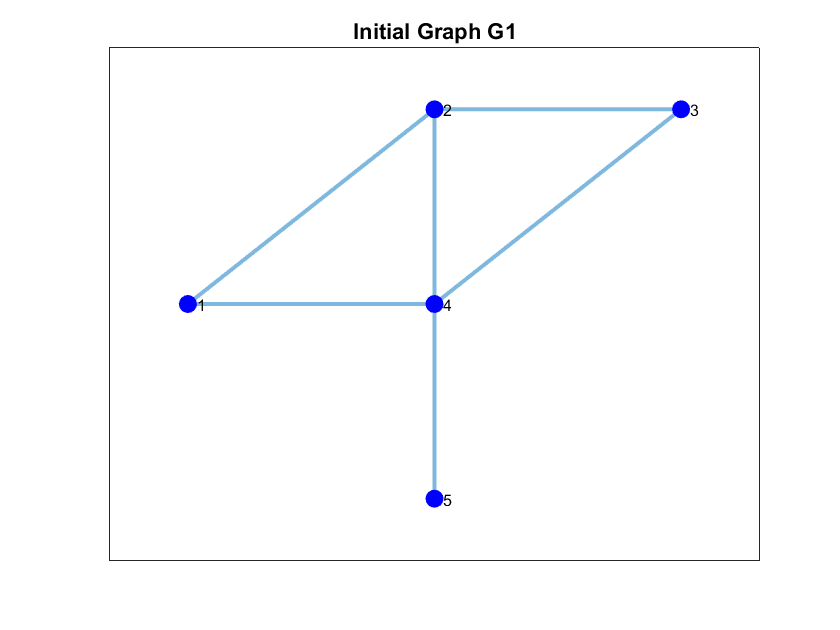

% GRAPH/DIGRAPH #1/2
Gx=[1 2 3 2 2];
Gy=[1 2 2 1 0];


% GRAPH #1
edgesG1 = [1 2; 1 4; 2 3; 2 4; 3 4; 4 5];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')

A=[0 1 0 1 0; 1 0 1 1 0; 0 1 0 1 0; 1 1 1 0 1; 0 0 0 1 0];
D=diag([2 3 2 4 1]);
L=D-A;

% CASE 1 - limit case
eps = 0.25;
P = eye(5)-eps*L

P =     0.5000    0.2500         0    0.2500         0
    0.2500    0.2500    0.2500    0.2500         0
         0    0.2500    0.5000    0.2500         0
    0.2500    0.2500    0.2500         0    0.2500
         0         0         0    0.2500    0.7500


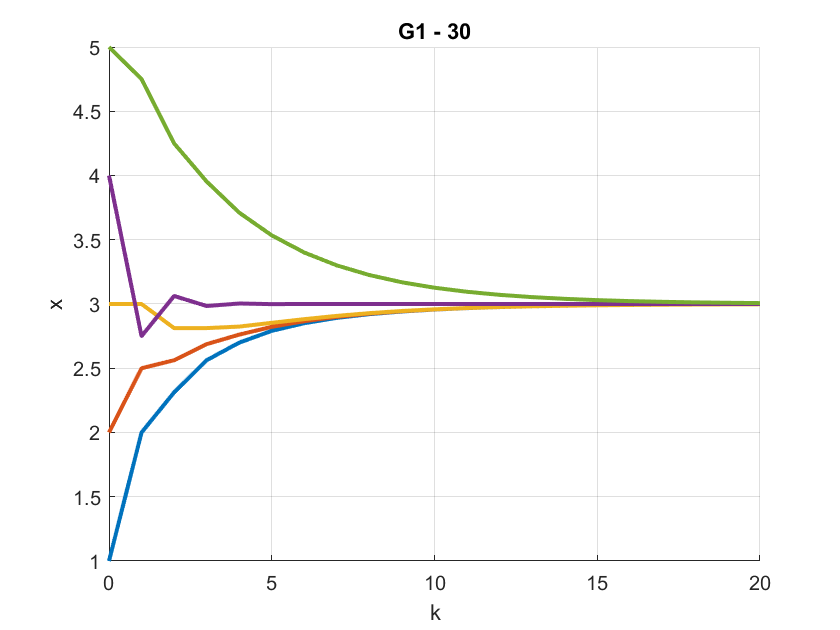

figure
x0=[1,2,3,4,5]';
%
xall=[]; kall=[];
for k=0:20; xall=[xall, P^k*x0]; kall=[kall, k]; end
xlabel('k'); ylabel('x'); hold on; grid on
plot(kall,xall,'LineWidth',2); title('G1 - 30')

#### STEP 1: Consensus of the agents

- Define communication graph (primitive P)

- Compute a consensus step and feed it to the corresponding UGV until consensus - the UGVs are massless points

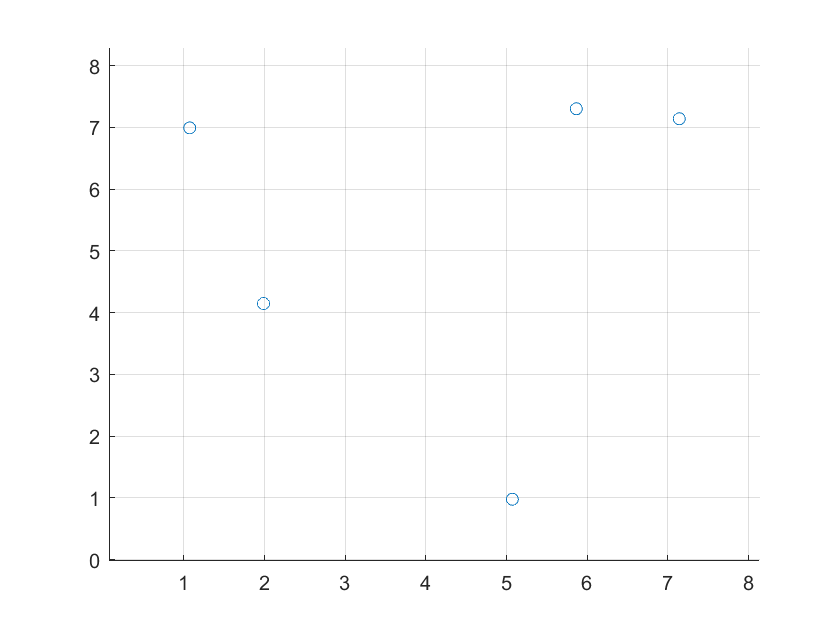

angles=[0,pi/4,pi/3,pi/2,3/4*pi,2/3*pi];
x0=randi(7,[2,5])';
e=0.1*randn([2,5])';
x0=x0+e;
%initial conditions
figure;
hold on;
grid on;
plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);

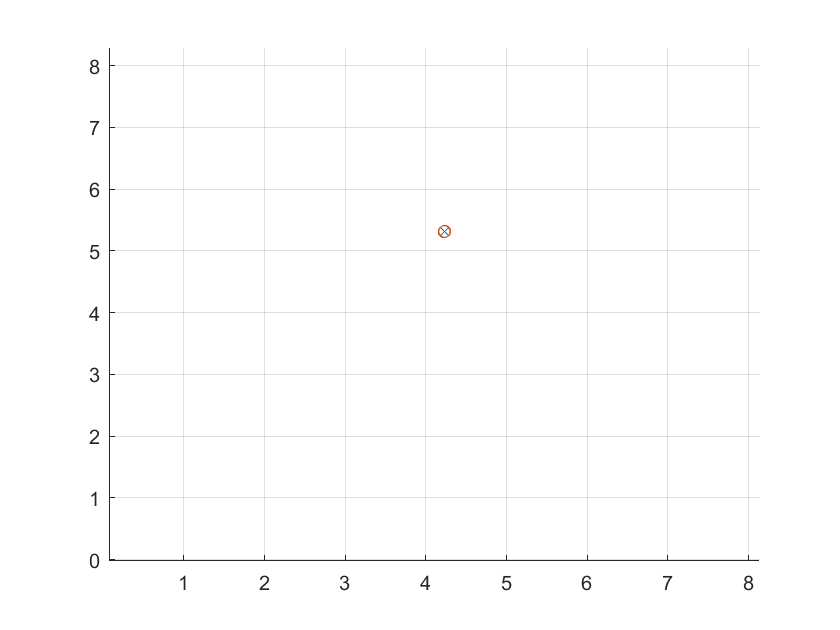

figure;
hold on;
grid on;
xc=mean(x0);
plot(xc(:,1),xc(:,2),"X");
x=zeros(size(x0));
hplot=plot(x0(:,1),x0(:,2),"o");
xlim([min(x0(:,1))-1,max(x0(:,1))+1]);
ylim([min(x0(:,2))-1,max(x0(:,2))+1]);
ugv_traj=zeros(5,2,20);
for k=1:20
    x(:,1)=(P^k)*x0(:,1);   
    x(:,2)=(P^k)*x0(:,2);
    ugv_traj(:,:,k)=x;
    set(hplot,"XData",x(:,1),"YData",x(:,2));
    pause(1);
    drawnow;
end

xc=x(1,:); %final point

%prepare time vector
%first ugv trajectory
p_x=zeros(1,20);
p_y=zeros(1,20);
ic=zeros(5,3);
trajectories=zeros(2,100,5);
%
for i=1:5
    
curr_traj=squeeze(ugv_traj(i,:,:));
p_x=curr_traj(1,:);
p_y=curr_traj(2,:);
ic(i,:)=[p_x(1),p_y(1),randsample(angles,1)]; 
xx = linspace(p_x(1),p_x(end));
yy = interp1(p_x,p_y,xx,'pchip');
trajectories(:,:,i)=[xx;yy];
end

ts1=timeseries(trajectories(:,:,1)');
ts2=timeseries(trajectories(:,:,2)');
ts3=timeseries(trajectories(:,:,3)');
ts4=timeseries(trajectories(:,:,4)');
ts5=timeseries(trajectories(:,:,5)');
%  ts1.time=0:0.1:10;
%  ts1.signals.values=trajectories(:,:,1);
%  ts1.signals.dimensions=[2,100];
%  
%   ts2.time=0:0.1:10;
%  ts2.signals.values=trajectories(:,:,2);
%  ts2.signals.dimensions=[2,100];
%  
%   ts3.time=0:0.1:10;
%  ts3.signals.values=trajectories(:,:,3);
%  ts3.signals.dimensions=[2,100];
%  
%  
%  ts4.time=0:0.1:10;
%  ts4.signals.values=trajectories(:,:,4);
%  ts4.signals.dimensions=[2,100];
%  
%  
%  ts5.time=0:0.1:10;
%  ts5.signals.values=trajectories(:,:,5);
%  ts5.signals.dimensions=[2,100];
 
% ts=timeseries(first_traj(:,2:end)');
% ts=timeseries([xx;yy]');
% angles=atan2(yy,xx);
% ts_theta=timeseries(angles);

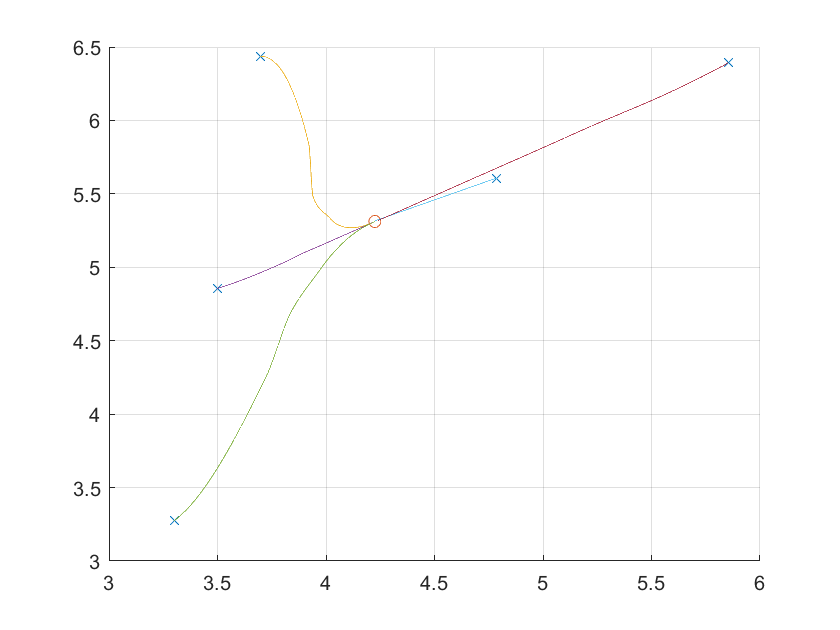

%run simulink
%plot trajectory
figure;
hold on;
grid on;
plot(ic(:,1),ic(:,2),"X");
plot(xc(:,1),xc(:,2),"O");
plot(p1.signals.values(:,1),p1.signals.values(:,2));
plot(p2.signals.values(:,1),p2.signals.values(:,2));
plot(p3.signals.values(:,1),p3.signals.values(:,2));
plot(p4.signals.values(:,1),p4.signals.values(:,2));
plot(p5.signals.values(:,1),p5.signals.values(:,2));

#### STEP 2: Movement of UGV

- Get the drone landing point 

- Design a trajectory according to some criterium (fastest, best, parabula...) and set it for each UGV

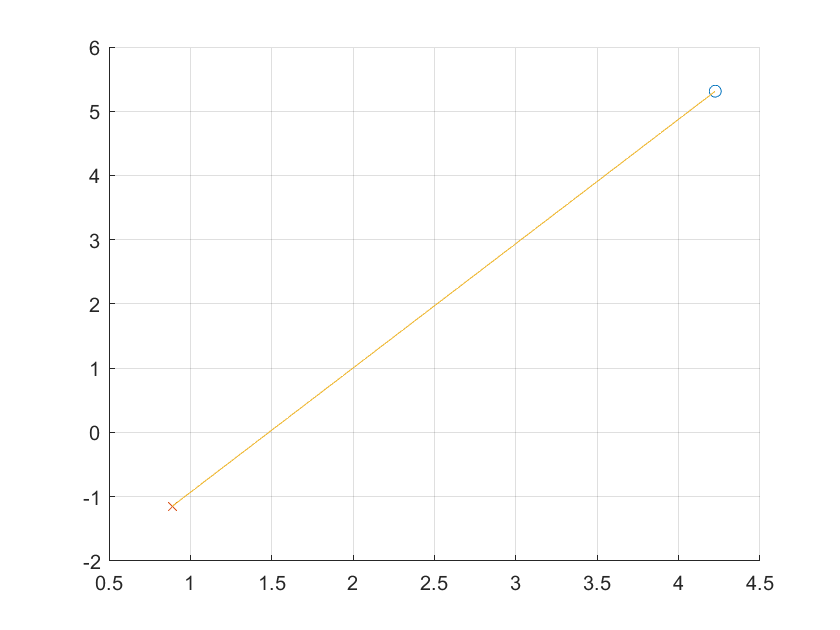

figure;

hold on;
grid on;
plot(xc(1),xc(2),"O");
xd=[randn([1,2]),0]; %landing point
plot(xd(1),xd(2),"X");

x_ugv=linspace(xc(1),xd(1));

y_ugv=interp1([xc(1),xd(1)],[xc(2),xd(2)],x_ugv,"linear");

plot(x_ugv,y_ugv);

for i=1:5
    trajectories(:,:,i)=[x_ugv;y_ugv];
end

ic(1,:)=[p1.signals.values(end,1),p1.signals.values(end,2),p1.signals.values(end,3)];
ic(2,:)=[p2.signals.values(end,1),p2.signals.values(end,2),p2.signals.values(end,3)]; 
ic(3,:)=[p3.signals.values(end,1),p3.signals.values(end,2),p3.signals.values(end,3)]; 
ic(4,:)=[p4.signals.values(end,1),p4.signals.values(end,2),p4.signals.values(end,3)]; 
ic(5,:)=[p5.signals.values(end,1),p5.signals.values(end,2),p5.signals.values(end,3)]; 

ts1=timeseries(trajectories(:,:,1)');
ts2=timeseries(trajectories(:,:,2)');
ts3=timeseries(trajectories(:,:,3)');
ts4=timeseries(trajectories(:,:,4)');
ts5=timeseries(trajectories(:,:,5)');

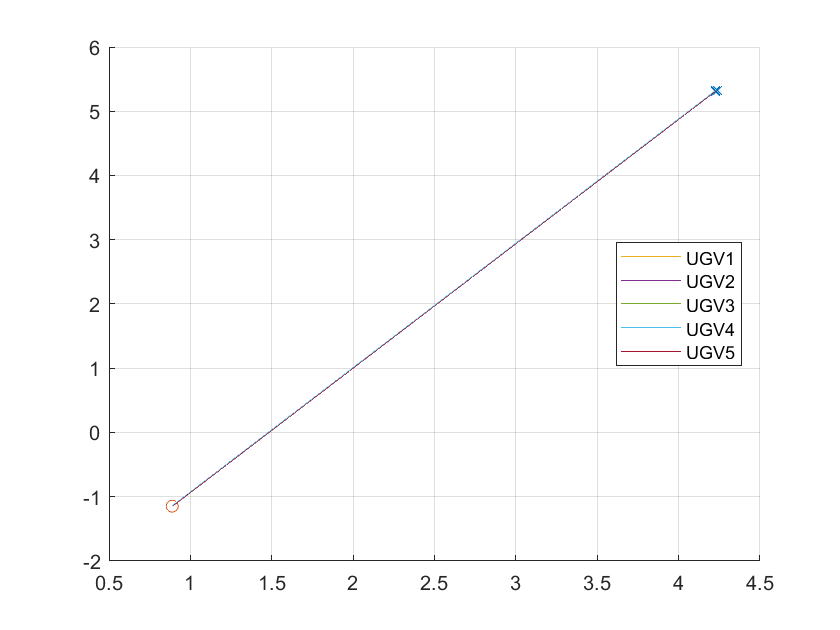

%run simulink
%plot trajectory
figure;
hold on;
grid on;
plot(ic(:,1),ic(:,2),"X");
plot(xd(:,1),xd(:,2),"O");
plot(p1.signals.values(:,1),p1.signals.values(:,2));
plot(p2.signals.values(:,1),p2.signals.values(:,2));
plot(p3.signals.values(:,1),p3.signals.values(:,2));
plot(p4.signals.values(:,1),p4.signals.values(:,2));
plot(p5.signals.values(:,1),p5.signals.values(:,2));
legend("","","UGV1","UGV2","UGV3","UGV4","UGV5","Location","best");

#### STEP 3: Drone landing

- Design a trajectory for the drone to its landing point according to some criterium.

%Wished positions and velocities (constraints)
% xd0=[randn([2,1]);5]'; %initial position of drone
xd0=[1,3,5];
xd; %landing position of drone
xd0_dot=zeros(3,1); %hovering starting position
xd_dot=zeros(3,1); %still final position
tf=20;
f=101;
t_samp=1:20;
          % Arrival, Waypoints, Orientation
constraints = [0,    xd0 ,   0,0,0;
              % tf/2,    xd(1),xd(2),xd0(3),    0,0,0;
               tf,    xd,  0,0,0;
               tf+1,xd,0,0,0];
trajectory = waypointTrajectory(constraints(:,2:4), ...
    'TimeOfArrival',constraints(:,1), ...
    'Orientation',quaternion(constraints(:,5:7),'eulerd','ZYX','frame'), ...
    'SampleRate',f, ...
    'Velocities',[0,0,0;0,0,0;0,0,0]);
tInfo = waypointInfo(trajectory)

tInfo = 3×4 table
    TimeOfArrival             Waypoints              Velocities       Orientation   
    _____________    ____________________________    ___________    ________________

          0               1          3          5    0    0    0    {1×1 quaternion}
         20          0.8884    -1.1471          0    0    0    0    {1×1 quaternion}
         21          0.8884    -1.1471          0    0    0    0    {1×1 quaternion}


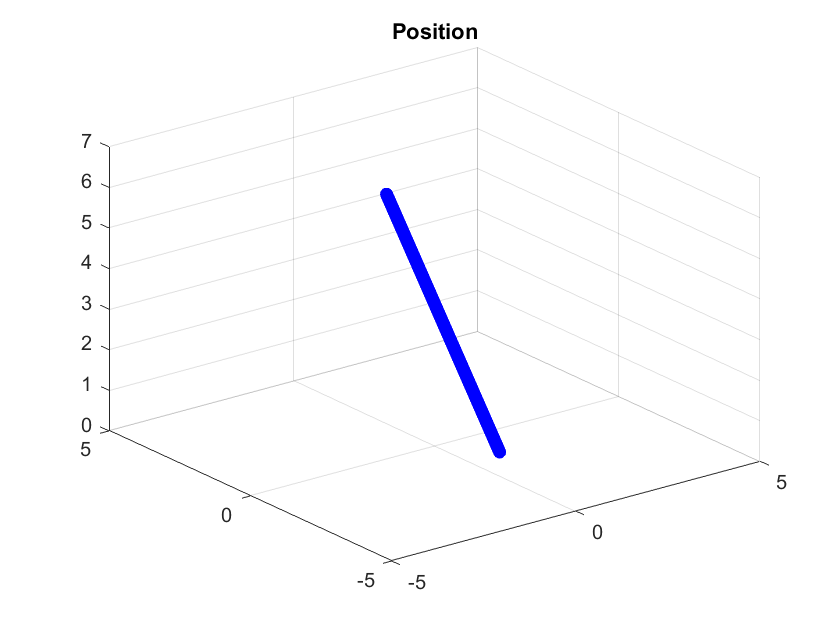


figure;
plot3(tInfo.Waypoints(1,1),tInfo.Waypoints(1,2),tInfo.Waypoints(1,3),'b*')
title('Position')
grid on
% daspect([1 1 1])
xlim([-5,5]);
ylim([-5,5]);
zlim([0,7]);
hold on
pos=zeros(tInfo.TimeOfArrival(end)*trajectory.SampleRate,3);
orient = zeros(tInfo.TimeOfArrival(end)*trajectory.SampleRate,1,'quaternion');
vel = zeros(tInfo.TimeOfArrival(end)*trajectory.SampleRate,3);
acc = vel;
angVel = vel;

count = 1;
pos(count,:)=tInfo.Waypoints(1,:);
orient(count,:)=tInfo.Orientation{1};
while ~isDone(trajectory)
   [pos(count+1,:),orient(count+1),vel(count+1,:),acc(count+1,:),angVel(count+1,:)] = trajectory();

   plot3(pos(count+1,1),pos(count+1,2),pos(count+1,3),'bo')
   count = count + 1;
end

t=0:1/trajectory.SampleRate:tInfo.TimeOfArrival(end);

ts_uav=timeseries(pos(1:end-1,:),t(1:end-1));
angles=timeseries(quat2eul(orient(1:end-1,:)),t(1:end-1));
fc = 3;

[b,a] = butter(2,fc/(f/2));
acc=filter(b,a,acc);
acceleration=timeseries(acc(1:end-1,:),t(1:end-1));

UAV landing

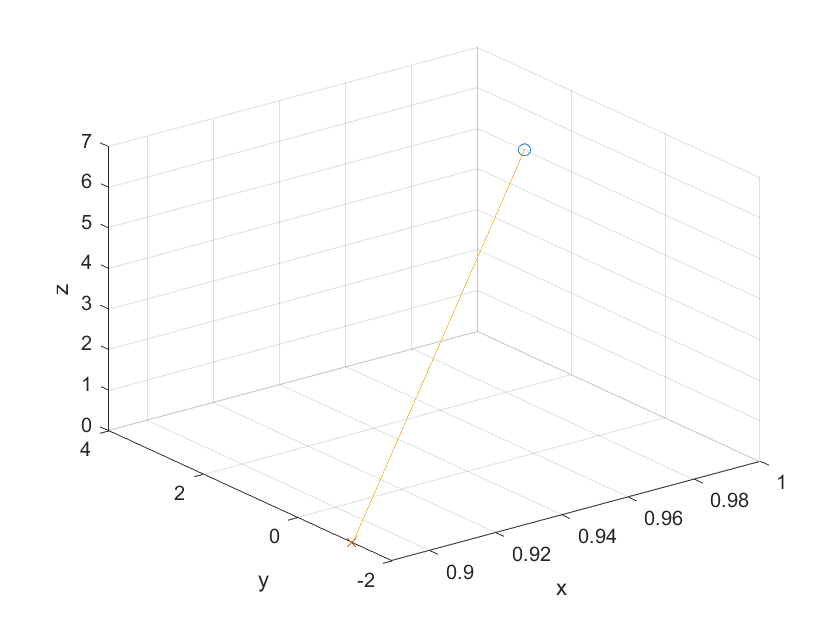

%simulink
figure;
plot3(xd0(1),xd0(2),xd0(3),"O",xd(1),xd(2),xd(3),"X",out.p.signals.values(:,1),out.p.signals.values(:,2),out.p.signals.values(:,3));
grid on;
zlim([0,7]);
xlabel("x");
ylabel("y");
zlabel("z");